## Control System Toolbox

La funzione ss(A,B,C,D) crea l'oggetto rappresentativo del modello nello spazio degli stati a partire dalle matrici A,B,C,D in formato numerico


$$A=\pmatrix{-1 & 4 \cr -4 & -1};\ B=\pmatrix{1\cr 0};\ C=\pmatrix{0 & 1};\ D=\pmatrix{2}$$


sys=ss([-1 4; -4 -1], [1;0], [0 1], 2);

La funzione lsim(sys,u,t,x0) simula l'evoluzione dello stato del sistema a partire dalle condizioni iniziali e ne restituisce uscita, tempo simulato e stato


$$t\in\{0,0.1, 0.2, \ldots, 10\}$$


t=0:0.01:10;


$$u=\underbrace{\pmatrix{0&0&\cdots &0}}_{\#t}
$$


u=zeros(size(t));


$$x_0=\pmatrix{1\cr0}$$


x0=[1,0];

La chiamata senza assegnazione, apre una finestra di analisi grafica per sistemi

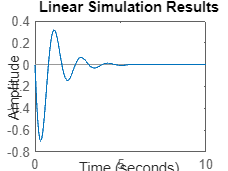

lsim(sys, u, t, x0)

Con la seguente opzione di chiamata, si ottiene invece il vettore di stato completo. In questo caso il sistema è di ordine 2, quindi il grafico in due dimensioni ne rappresenta la traiettoria

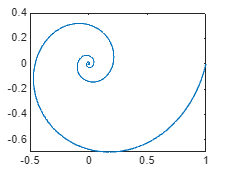

[y, tout, x]=lsim(sys, u, t, x0);
plot(x(:,1),x(:,2))

Nota anche la derivata dello stato, si può visualizzare la direzione della traiettoria

xn=x(1:5:end,:);
un=u(1:5:end);


$$v=\dot{x}=Ax+Bu$$


% non funziona
v=(sys.A*xn+sys.B*un);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Related documentation

hold on
quiver(xn(:,1), xn(:,2), v(:,1),v(:,2))
